clear all;
%currentFolder = pwd
%load('200V_Star_Config_50APeak1.mat')
%load('200V_Delta_Config_50APeak.mat')
load("60V_Delta_Config_50APeak.mat")

MOI = .18

MOI = 0.1800

gearRatio = 3

gearRatio = 3

outputRPM = var3;
outputTorque = cell_Torque{1,1};
numMotors = 2;

weaponRadius = .1905 %weapon radius in meters

weaponRadius = 0.1905

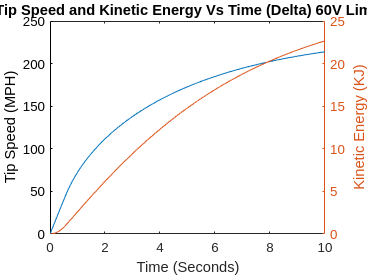


dt = 0.01;
time_array = linspace(0,10,10*1/dt);



newOutputRPM = [0];

previousVelocity = 0;
currentVelocity = 0;
NewAngularAcceleration = [0];
TESToutputTorque = time_array;
TESTARRAY = [];

RADToRPM = 9.5493;
RPMToRAD = 1/RADToRPM;


for n = 2 : length(time_array)

    previousVelocity = newOutputRPM(n-1)*RADToRPM*gearRatio;
    if previousVelocity > outputRPM(length(outputRPM))
        break
    else
        for l = 1 : length(outputRPM)
            if ge(previousVelocity,outputRPM(l)) && le(previousVelocity, outputRPM(l+1))
                index = l;
            end
        end
        m = ((outputTorque(index)-outputTorque(index+1))/(outputRPM(index)-outputRPM(index+1)));
        b = outputTorque(index)-(m*outputRPM(index));
        
        torque = m*previousVelocity+b;
        torque = torque*gearRatio*numMotors*.9-(.5*(previousVelocity/gearRatio)^2*4.5E-7);
        % Torque Losses
        
        TESToutputTorque(n)=torque;
        angularAccel = torque/MOI;
        TESTARRAY(n) = angularAccel;


        newOutputRPM(n) = (previousVelocity*RPMToRAD/gearRatio)+angularAccel*dt;
    end
end

newOutputRPM = newOutputRPM;
kineticEnergy = .5*MOI*(newOutputRPM.*newOutputRPM);
kineticEnergy = kineticEnergy/1000;
tipSpeed = newOutputRPM*(weaponRadius*2.23694);
newOutputRPM = newOutputRPM * RADToRPM;

plotTime = linspace(0, length(newOutputRPM)*dt,length(tipSpeed));


figure(2);

plot(plotTime, tipSpeed)
title('Tip Speed and Kinetic Energy Vs Time (Delta) 60V Limit')
xlabel('Time (Seconds)')
ylabel('Tip Speed (MPH)')

yyaxis right
plot(plotTime, kineticEnergy)
ylabel('Kinetic Energy (KJ)')

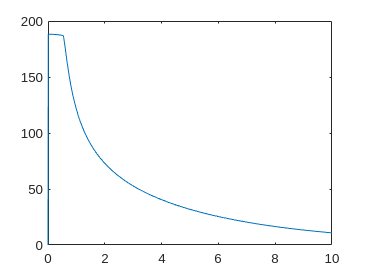



figure(4);
title('Test Plot')
plot(plotTime,TESTARRAY)